# Title & Project Overview (Steady state model)

% This Live Script documents the complete thermal design process for a radiator to cool the motor and motor controllers.

## Calculating Required Heat Rejection

import py.CoolProp.CoolProp.*
P_peak = 35000; % peak operating power of motor (W), F-MOT motor datasheet
efficiency = 0.93; % worst efficiency according to datasheet (%)
Q_motor = P_peak - efficiency*P_peak; % heat loss through water (W)
Q_motor_controller = 750; % max power dissipation according to datasheet, (W)
Q_target = Q_motor + Q_motor_controller; % (W)

## Fixed Inputs & Constants

% operating conditions 
mdot_coolant = 18; % mass flow rate of coolant (L/min), according to mc datasheet optimal at 10
T_coolant_in = 55; %(°C), max 70degC for motor controller 
T_air_in = 25; %ambient air temp of 25 assumed (°C)
v_air = 5; %velocity of air assumed to be 5m/s (first iter from aero team), update accordingly

% fixed geometry (all in m)
d = 0.032; % common values added as options for depth of radiator 
H = 0.2; % 200mm used in previous code  
a_tube = 0.002; % dimensions of rectangular tube, height as 2mm
b_tube = d; % width of tube taken equal to depth of radiator
a_water = a_tube-0.0003*2; % tube dimension = 0.3mm
b_water = b_tube-0.0003*2; % these are dimensions of water channel
alpha = a_water/b_water; % aspect ratio
% using data from the old code regarding fin dimensions
f_height = 0.008; % (8mm)
f_thickness = 0.0001; % (0.1mm)
% fin width same as radiator width 
tube_pitch = a_tube + f_height; % height of tube(2mm) + fin space(8mm), used to calculate number of tubes 
D_h_tube = (4*a_water*b_water)/(2*(a_water+b_water)); % hydraulic diameter of tube
A_tube = a_water*b_water; % tube cross sectional area (m²)

% air properties at 25°C
T_air = 298.15; % Temperature in Kelvin (25°C)
P_air = 101325; % Pressure in Pascals (1 atm)

rho_air = PropsSI('D', 'T', T_air, 'P', P_air, 'Air'); % density (kg/m^3)
mu_air = PropsSI('V', 'T', T_air, 'P', P_air, 'Air'); % dynamic viscosity (Pa*s)
k_air = PropsSI('L', 'T', T_air, 'P', P_air, 'Air'); % thermal conductivity (W/m*K)
cp_air = PropsSI('C', 'T', T_air, 'P', P_air, 'Air'); % specific heat capacity (J/kg*K)
Pr_air = PropsSI('Prandtl', 'T', T_air, 'P', P_air, 'Air'); % Prandtl number

% parameter ranges 
fpi_range = linspace(8,25,18); %fins per inch
A_face_range = linspace(0.01, 0.20, 100); %radiator face area (m²)

%% Water Properties as Functions of Temp
P_water = 101325; % 1 atm 
rho_water = PropsSI('D', 'T', 323.15, 'P', P_water, 'Water');
cp_water = PropsSI('C', 'T', 323.15, 'P', P_water, 'Water');
% density and thermal conductivity barely change over selected temp range,
% properties assumed at 50degC, needed for further calculation
mdot_coolant_kgs = (mdot_coolant*rho_water)/60000; %(L/min) to (kg/s)
deltaT = Q_target/(mdot_coolant_kgs*cp_water);
T_coolant_out = T_coolant_in - deltaT;
T_avg = (T_coolant_out+T_coolant_in)/2;
T_avg_K = T_avg + 273.15;
k_water = PropsSI('L', 'T', T_avg_K, 'P', P_water, 'Water');
mu_water = PropsSI('V', 'T', T_avg_K, 'P', P_water, 'Water');
Pr_water = PropsSI('Prandtl', 'T', T_avg_K, 'P', P_water, 'Water');

## Fin Density (m2/m3) to FPI (Fins per Inch)

% function [FPI] = sigma_to_fpi(sigma,f_height,f_thickness)
% p = 2*(f_height-f_thickness)/(sigma*f_height-2); %fin pitch (m)
% p_in = p/0.0254; %pitch (inches)
% FPI = 1/p_in;
% end

## Heat Transfer Function Inputs

% constants passed into the heat transfer function radiator_Q (defined at the end of this script)
% A_face, fpi, H and mdot_coolant_kgs are the inputs that change between calls, everything else is fixed
params.d = d;
params.a_tube = a_tube;
params.a_water = a_water;
params.b_water = b_water;
params.alpha = alpha;
params.f_height = f_height;
params.f_thickness = f_thickness;
params.tube_pitch = tube_pitch;
params.D_h_tube = D_h_tube;
params.A_tube = A_tube;
params.rho_air = rho_air;
params.mu_air = mu_air;
params.cp_air = cp_air;
params.Pr_air = Pr_air;
params.v_air = v_air;
params.rho_water = rho_water;
params.cp_water = cp_water;
params.k_water = k_water;
params.mu_water = mu_water;
params.Pr_water = Pr_water;
params.T_coolant_in = T_coolant_in;
params.T_air_in = T_air_in;

## Heat Transfer Calculations

Q_predicted = zeros(length(A_face_range), length(fpi_range)); %results matrix 
W_calculated = zeros(length(A_face_range), length(fpi_range)); %width matrix 
epsilon_f_mat = zeros(length(A_face_range), length(fpi_range)); %fin effectiveness matrix

for i = 1:length(A_face_range)
    for j = 1:length(fpi_range)

        A_face = A_face_range(i);
        fpi = fpi_range(j);

        [Q_predicted(i,j), info] = radiator_Q(A_face, fpi, H, mdot_coolant_kgs, params);
        W_calculated(i,j) = info.W; %width stored for plotting
        epsilon_f_mat(i,j) = info.epsilon_f; %fin effectiveness stored for the table
    end
end

%water side flow quantities (depend only on H and mdot_coolant_kgs, so they are the same for every A_face and fpi)
mdot_tube = info.mdot_tube; %mass flow rate per tube
v_water = info.v_water; %velocity of water in each tube
Re_water = info.Re_water;
i_selected = 1; % printing logic for fin effectiveness table
eps_f_table = table(fpi_range',epsilon_f_mat(i_selected,:)','VariableNames',{'FPI','FinEffectiveness'});
disp(eps_f_table);

    FPI    FinEffectiveness
    ___    ________________

     8          76.679     
     9          76.561     
    10          76.447     
    11          76.338     
    12          76.232     
    13          76.129     
    14           76.03     
    15          75.932     
    16          75.837     
    17          75.744     
    18          75.652     
    19          75.562     
    20          75.474     
    21          75.387     
    22          75.301     
    23          75.217     
    24          75.133     
    25           75.05     



## Plotting Heat Rejected with Area and Fin Density

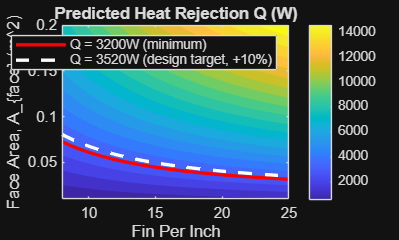

figure;
contourf(fpi_range, A_face_range, Q_predicted, 20, 'LineColor', 'none');
colorbar;
xlabel('Fin Per Inch');
ylabel('Face Area, A_{face} (m^2)');
title('Predicted Heat Rejection Q (W)');
hold on;

% Critical boundary - minimum requirement
contour(fpi_range, A_face_range, Q_predicted, [Q_target Q_target], 'r', 'LineWidth', 2);

% Adding a safety factor of 1.1 (considering all the worst case conditions assumed)
contour(fpi_range, A_face_range, Q_predicted, [Q_target*1.1 Q_target*1.1], 'w--', 'LineWidth', 2);

legend('', sprintf('Q = %gW (minimum)', Q_target), sprintf('Q = %gW (design target, +10%%)', Q_target * 1.1));
hold off;

## Plot Width of Radiator

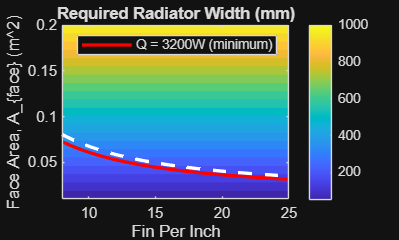

figure;
contourf(fpi_range, A_face_range, W_calculated*1000, 20, 'LineColor', 'none');
c = colorbar;
clim([min(W_calculated(:))*1000, max(W_calculated(:))*1000]);
xlabel('Fin Per Inch');
ylabel('Face Area, A_{face} (m^2)');
title('Required Radiator Width (mm)');
hold on;
contour(fpi_range, A_face_range, Q_predicted, [Q_target Q_target], 'r', 'LineWidth', 2);
contour(fpi_range, A_face_range, Q_predicted, [Q_target*1.1 Q_target*1.1], 'w--', 'LineWidth', 2);
legend('', sprintf('Q = %gW (minimum)', Q_target));
hold off;

## Extract exact A_face value and pressure drop at a given fpi

C = contourc(fpi_range, A_face_range, Q_predicted, [Q_target Q_target]);
fpi_contour = C(1,2:end);
A_face_contour = C(2,2:end);

[fpi_sorted, sort_idx] = sort(fpi_contour);
A_face_sorted = A_face_contour(sort_idx);

fpi_query = 18; %CHANGE HERE
A_face_min = interp1(fpi_sorted, A_face_sorted, fpi_query);
W_min = A_face_min/H;
fRe = 96*(1 - 1.3553*alpha + 1.9467*alpha^2 - 1.7012*alpha^3 + 0.9564*alpha^4 - 0.2537*alpha^5); % shah & london curve fit 
Kinf = 0.6796 + 1.2197*alpha + 3.3089*alpha^2 - 9.5921*alpha^3 + 8.9089*alpha^4 - 2.9959*alpha^5;   % developing-flow term
f_darcy = fRe/Re_water;
P_drop_water = (f_darcy*(W_min/D_h_tube) + Kinf)*(rho_water*v_water^2/2)*((info.n_tubes)^2); %pressure drop across radiator 
fprintf('At fpi = %.0f, minimum A_face (Q=%.0fW) = %.4f m^2\n', fpi_query, Q_target, A_face_min);

At fpi = 18, minimum A_face (Q=3200W) = 0.0391 m^2


fprintf('At chosen fpi and A_face_min (H=%.0fmm), Pressure drop = %.2fPa\n', H*1000, P_drop_water);

At chosen fpi and A_face_min (H=200mm), Pressure drop = 103585.17Pa



Q_target_margin = Q_target*1.1;
C2 = contourc(fpi_range, A_face_range, Q_predicted, [Q_target_margin Q_target_margin]);
fpi_contour2 = C2(1, 2:end);
A_face_contour2 = C2(2, 2:end);
[fpi_sorted2, sort_idx2] = sort(fpi_contour2);
A_face_sorted2 = A_face_contour2(sort_idx2);

A_face_design_target = interp1(fpi_sorted2, A_face_sorted2, fpi_query);
W_min_design = A_face_design_target/H;
P_drop_water_design = (f_darcy*(W_min_design/D_h_tube) + Kinf)*(rho_water*v_water^2/2)*((info.n_tubes)^2); %pressure drop across radiator
fprintf('At fpi = %.0f, design target A_face (Q=%.0fW, +10%%) = %.4f m^2\n', fpi_query, Q_target_margin, A_face_design_target)

At fpi = 18, design target A_face (Q=3520W, +10%) = 0.0434 m^2


fprintf('At chosen fpi and A_face_min (H=%.0fmm), Pressure drop = %.2fPa\n', H*1000, P_drop_water_design);

At chosen fpi and A_face_min (H=200mm), Pressure drop = 113069.75Pa


## COMSOL validation parameters

% h_air at design point for comsol validation
% (h_air does not depend on A_face, A_face_min is only there to complete the function call)
[~, info_design] = radiator_Q(A_face_min, fpi_query, H, mdot_coolant_kgs, params);
fprintf('h_air for boundary condition = %.4f', info_design.h_air);

h_air for boundary condition = 126.0031


% Q_rejected at a certain Width 
W = 0.24685; % cad is 246.85mm in width 
fpi = 18;
A_face = W*H;
[Q, info_comsol] = radiator_Q(A_face, fpi, H, mdot_coolant_kgs, params);
Q_tube = Q/info_comsol.n_tubes;
dT_water = Q/(mdot_coolant_kgs*cp_water);               
T_out = T_coolant_in - dT_water;
fprintf('Q_rejected_total = %.2fW, Q_rejected_tube = %.2fW', Q, Q_tube);

Q_rejected_total = 3955.74W, Q_rejected_tube = 197.79W

fprintf('T_out = %.2f degC (%.2f K), dT = %.2f K\n', T_out, T_out+273.15, dT_water);

T_out = 51.81 degC (324.96 K), dT = 3.19 K



% comsol assumes constant temp for air (25degC), we can replicate that in
% matlab with C_air = infinity and using simplified epsilon relation
Q_tube_comsol = 287; % Q_rejected_tube from comsol
UA_tube = info_comsol.UA/info_comsol.n_tubes;
C_water_tube = info_comsol.C_water/info_comsol.n_tubes;
Q_tube_inf_air = C_water_tube*(T_coolant_in-T_air_in)*(1-exp(-UA_tube/C_water_tube)); % simplified e_ntu, Q = C_min*deltaT*(1-e^(-NTU)) where NTU = UA/C_min
UA_tube_comsol = -C_water_tube*log(1 - Q_tube_comsol/(C_water_tube*(T_coolant_in-T_air_in))); % effective UA implied by comsol
fprintf('Q_tube (infinite air) = %.2fW, UA_tube_matlab = %.3f, UA_tube_comsol = %.3f W/K', Q_tube_inf_air, UA_tube, UA_tube_comsol);

Q_tube (infinite air) = 264.36W, UA_tube_matlab = 9.505, UA_tube_comsol = 10.391 W/K


% Air-side inputs for the COMSOL boundary PDE (cb)
n_tubes = floor(H/tube_pitch); 
A_face = W*H; 
mdot_air_total = rho_air*v_air*A_face; % total air mass flow (kg/s)
mdot_air_cell = mdot_air_total/n_tubes; % air through one tube pitch (kg/s)

W_perp = (info_comsol.A_primary + info_comsol.A_secondary)/(d*info_comsol.n_tubes); % width of wetted perimeter (including both tube + fin)
beta = mdot_air_cell*cp_air/W_perp; % W/(m*K), magnitude of beta

fprintf('cp_air = %.2f[J/(kg*K)]\n', cp_air);

cp_air = 1006.31[J/(kg*K)]


fprintf('mdot_air_cell = %.6f[kg/s]\n', mdot_air_cell);

mdot_air_cell = 0.014617[kg/s]


fprintf('W_perp = %.5f[m]\n', W_perp);

W_perp = 3.25764[m]


fprintf('beta = %.4f[W/(m*K)]\n', beta);

beta = 4.5154[W/(m*K)]


## Checking dependency on H

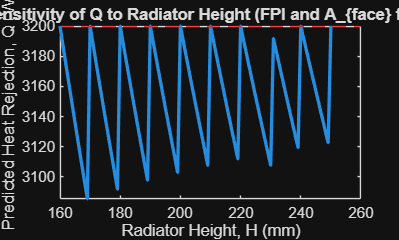

H_range = linspace(0.16, 0.25, 100); % team's given range: 160-250m

A_face_fixed = A_face_min;% chosen design point
fpi_fixed = fpi_query;% chosen design point

Q_vs_H = zeros(size(H_range));

for m = 1:length(H_range)
    % H is what is changing (n_tubes and W = A_face/H are recalculated inside the function)
    Q_vs_H(m) = radiator_Q(A_face_fixed, fpi_fixed, H_range(m), mdot_coolant_kgs, params);
end

plot(H_range*1000, Q_vs_H, 'LineWidth', 2)
xlabel('Radiator Height, H (mm)')
ylabel('Predicted Heat Rejection, Q (W)')
yline(Q_target, 'r--', 'Minimum Requirement')
title('Sensitivity of Q to Radiator Height (FPI and A_{face} fixed)')

% this plot shows us that given an area and fin density, varying height
% doesnt have a significant change in heat rejection so calculating heat
% according to fixed height of 350mm for the previous section was fine

## Checking dependency on coolant flow rate

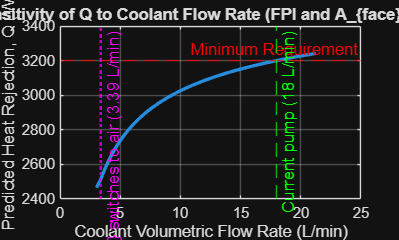

mdot_range_test = linspace(0.05, 0.35, 100);% (kg/s) or (3-24L/min), later changed to L/min to showcase in the graph

A_face_fixed2 = A_face_min;% chosen design point
fpi_fixed2 = fpi_query;% chosen design point
H_fixed = 0.2;% chosen design point0

Q_vs_mdot = zeros(size(mdot_range_test));

for p = 1:length(mdot_range_test)
    mdot_coolant_test = mdot_range_test(p);
    % water side h (depends on mdot_coolant_test) and C_water are recalculated inside the function
    Q_vs_mdot(p) = radiator_Q(A_face_fixed2, fpi_fixed2, H_fixed, mdot_coolant_test, params);
end
%at lower mdot, cmin = cwater instead of cair so Q drastically increases in
%the start but diminishing returns as later cwater > cair so q = cmin*delta t
%gets a fixed cmin = cair, and delta t only changed by U which isnt
%affected much by water

V_dot_Lmin = (mdot_range_test ./ rho_water)*60000; % convert kg/s to L/min
mdot_crossover_kgs = rho_air*v_air*cp_air*A_face_fixed2/cp_water;
mdot_crossover_Lmin = mdot_crossover_kgs/rho_water*60000;
figure;
plot(V_dot_Lmin, Q_vs_mdot, 'LineWidth', 2)
xlabel('Coolant Volumetric Flow Rate (L/min)')
ylabel('Predicted Heat Rejection, Q (W)')
yline(Q_target, 'r--', 'Minimum Requirement')
xline(mdot_coolant, 'g--', sprintf('Current pump (%g L/min)', mdot_coolant))
xline(mdot_crossover_Lmin, 'm:', sprintf('C_{min} switches to air (%.2f L/min)', mdot_crossover_Lmin), 'LineWidth', 1.5)
title('Sensitivity of Q to Coolant Flow Rate (FPI and A_{face} fixed)')
grid on

## Testing min A_face at diff FPI

fpi_test_points = fpi_range;

C_q = contourc(fpi_range, A_face_range, Q_predicted, [Q_target Q_target]);
fpi_q = C_q(1, 2:end);
A_face_q = C_q(2, 2:end);
[fpi_q_sorted, idx] = sort(fpi_q);
A_face_q_sorted = A_face_q(idx);

fprintf('%-10s %-15s %-12s\n', 'FPI', 'A_face (m^2)', 'Width (mm)')

FPI        A_face (m^2)    Width (mm)  


for f = fpi_test_points
    A_face_at_s = interp1(fpi_q_sorted, A_face_q_sorted, f);
    W_at_s = A_face_at_s/H*1000;
    fprintf('%-10d %-15.4f %-12.1f\n', f, A_face_at_s, W_at_s)
end

8          0.0727          363.5       
9          0.0663          331.5       
10         0.0610          305.2       
11         0.0566          283.2       
12         0.0529          264.7       
13         0.0498          248.9       
14         0.0470          235.2       
15         0.0447          223.4       
16         0.0426          213.0       
17         0.0408          203.9       
18         0.0391          195.7       
19         0.0377          188.5       
20         0.0364          182.0       
21         0.0352          176.2       
22         0.0342          171.0       
23         0.0332          166.2       
24         0.0324          161.9       
25         0.0316          157.9       


## Heat Transfer Function

function [Q, info] = radiator_Q(A_face, fpi, H, mdot_coolant_kgs, params)
% radiator_Q  predicted heat rejection Q (W) of the radiator for one design point
% inputs:  A_face (m^2), fpi (fins per inch), H (m), mdot_coolant_kgs (kg/s), params (struct of fixed constants)
% outputs: Q (W), info (struct with width and intermediate quantities, optional)

    % fixed geometry, air and water properties, operating temperatures
    d = params.d;
    a_tube = params.a_tube;
    a_water = params.a_water;
    b_water = params.b_water;
    alpha = params.alpha;
    f_height = params.f_height;
    f_thickness = params.f_thickness;
    tube_pitch = params.tube_pitch;
    D_h_tube = params.D_h_tube;
    A_tube = params.A_tube;
    rho_air = params.rho_air;
    mu_air = params.mu_air;
    cp_air = params.cp_air;
    Pr_air = params.Pr_air;
    v_air = params.v_air;
    rho_water = params.rho_water;
    cp_water = params.cp_water;
    k_water = params.k_water;
    mu_water = params.mu_water;
    Pr_water = params.Pr_water;
    T_coolant_in = params.T_coolant_in;
    T_air_in = params.T_air_in;

    W = A_face/H;

    %water side convection heat transfer coefficient
    n_tubes = floor(H/tube_pitch); %number of tubes
    mdot_tube = mdot_coolant_kgs/(n_tubes); %mass flow rate per tube
    v_water = mdot_tube/(rho_water*A_tube); %velocity of water in each tube
    Re_water = (rho_water*v_water*D_h_tube)/mu_water;
    if Re_water < 2300
        Nu_fd = 8.235*(1 - 2.0421*alpha + 3.0853*alpha^2 - 2.4765*alpha^3 + 1.0578*alpha^4 - 0.1861*alpha^5);
        % this is a curve fit from tabulated data from shah & london, flow is
        % assuming fully developed laminar flow in rectangular tube with aspect
        % ratio alpha
        Gz = (D_h_tube/W)*Re_water*Pr_water; % graetz number, takes it that flow is developing across length of water channel
        Nu_water = Nu_fd + 0.0668*Gz/(1 + 0.04*Gz^(2/3)); % hausen entry correction, length-averaged Nu for thermally developing flow (enhances Nusselt number)
    else
        Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.3); %turbulent
    end
    h_water = (Nu_water*k_water)/D_h_tube;

    %air side convection heat transfer coefficient  
    sigma_c = 1-((fpi*f_height*f_thickness)/0.0254+a_tube)/(a_tube+f_height); %contraction factor
    G_air = rho_air*v_air/sigma_c; % mass flux
    f_spacing = 0.0254/fpi - f_thickness;
    D_h_fin = (4*f_spacing*f_height)/(2*(f_spacing+f_height)); %hydraulic diameter of fin channel
    Re_air = G_air*D_h_fin/mu_air; %reynolds numbers
    J_air = 0.174/(Re_air)^0.383; % Colburn j-factor 
    h_air = J_air*G_air*cp_air/(Pr_air^(2/3));

    %capacity rates 
    C_air = rho_air*v_air*cp_air*A_face;
    C_water = mdot_coolant_kgs*cp_water;
    C_min = min(C_air,C_water);
    C_max = max(C_air,C_water);
    C_star = C_min/C_max;

    % A_air_eff calculation
    A_primary = 2*d*W*n_tubes*(1 - f_thickness*fpi/0.0254); % tube and air contact surface area 
    A_water_inner = 2*(a_water+b_water)*W*n_tubes; % tube and water contact area
    A_secondary = 2*f_height*d*fpi*W*n_tubes/0.0254; % fin and air contact surface area  
    k_fin = 237; %thermal conductivity of aluminium (fin material)
    % fin efficiency 
    m = sqrt(2*h_air/(k_fin*f_thickness));
    L_c = f_height/2 + f_thickness/2;
    eta_f = tanh(m*L_c)/(m*L_c);
    eta_0 = 1-(A_secondary/(A_primary+A_secondary))*(1-eta_f); %surface efficiency
    A_air_eff = eta_0*(A_primary+A_secondary); %surface efficiency 
    % fin effectiveness
    A_c_b = f_thickness*d*n_tubes*2*fpi*W/0.0254;
    epsilon_f = eta_f*(A_secondary/A_c_b);

    % Thermal resistances
    R_air = 1/(h_air*A_air_eff);
    R_water = 1/(h_water*A_water_inner);

    % Overall conductance
    UA = 1/(R_air + R_water);

    NTU = UA/C_min; %number of transfer units
    epsilon = 1-exp((NTU^0.22/C_star)*(exp(-C_star*NTU^0.78)-1)); 

    Q = epsilon*C_min*(T_coolant_in-T_air_in);

    % intermediate quantities other sections need (only used if a second output is requested)
    info.W = W;
    info.n_tubes = n_tubes;
    info.mdot_tube = mdot_tube;
    info.v_water = v_water;
    info.Re_water = Re_water;
    info.h_water = h_water;
    info.h_air = h_air;
    info.epsilon_f = epsilon_f;
    info.UA = UA;
    info.C_water = C_water;
    info.A_primary = A_primary;
    info.A_secondary = A_secondary;
end